## 神经编码特征模式分析

Neural representation, encoding mechanism, pattern, ensemble

王韶莉，苏峰，杨鹤

2021-12-04 ---- NeuAna20211201_v2.mlx,   Add the analysis of joint entropy

2021-12-16 ---- NeuAna20211201_v3_encodingSimi  Add cosine similarity analysis

2021-12-28 ---- NeuAna20211201_v4_encodingSimi  Add analysis of joint mutual information

2024-11-15 ---- NeuAna20241115_v5.mlx, Improved with chatGPT

addpath('Neuroscience-Information-Theory-Toolbox-master');

addpath("D:\MATLAB\R2021b\toolbox\sort_nat");

## 加载数据

数据格式：目标文件夹中，包含2个文件夹, intensity, spike

***TargetFolder   *****弹窗需要选择的文件夹，不要选择到子文件夹**

*        intensity*

*        spike*

clc
clear

加载 intensity and spike data

调试过程中反复加载太多excel文件比较费时间，可以选择使用已经存在的 DataOrigi.mat 文件

% Select the target folder
TarFolder = uigetdir;
tarMat = 'DataOrigi.mat';
tarMatPath = fullfile(TarFolder, tarMat);

% Flag to determine if saved data should be used
useSavedDataFlag = 0;  % Set to 1 to use existing .mat file

if useSavedDataFlag && exist(tarMatPath, 'file')
    disp('Loading saved data...');
    load(tarMatPath, 'StructData', 'StructPara');
else
    % Reload data from Excel files
    disp('Loading data from Excel files...');
    
    % Save the current directory
    pathCurr = pwd;
    
    % Get intensity files
    pathIntensity = fullfile(TarFolder, 'intensity');
    if ~exist(pathIntensity, 'dir')
        error('Intensity folder not found: %s', pathIntensity);
    end
    cd(pathIntensity);
    listIntensi = dir('*.xlsx');
    
    % Get spike files
    pathSpike = fullfile(TarFolder, 'spike');
    if ~exist(pathSpike, 'dir')
        error('Spike folder not found: %s', pathSpike);
    end
    cd(pathSpike);
    listSpike = dir('*.xlsx');
    
    % Return to the original directory
    cd(pathCurr);
    
    % Error check: Ensure the number of intensity files matches spike files
    if length(listIntensi) ~= length(listSpike)
        error('Number of intensity files does not match the number of spike files.');
    end
    
    % Sort file names in a natural order
    liseName = {listIntensi.name};
    if exist('sort_nat', 'file') == 2
        [~, index] = sort_nat(liseName);
    else
        error('The "sort_nat" function is required but not found in the MATLAB path.');
    end
    listIntensi = listIntensi(index);
    listSpike = listSpike(index);
    
    % Initialize the StructData structure
    StructData = [];
    
    % Loop over each intensity and spike file pair
    for ci = 1:length(listIntensi)
        disp(['Processing file ', num2str(ci), ' of ', num2str(length(listIntensi)), ': ', listSpike(ci).name]);
        
        % Load intensity data
        TR1 = fullfile(listIntensi(ci).folder, listIntensi(ci).name);
        TR2 = xlsread(TR1);  % Read intensity Excel file
        StructData(ci).Intensity = TR2;
        
        % Load spike data
        TR1 = fullfile(listSpike(ci).folder, listSpike(ci).name);
        TR2 = xlsread(TR1);  % Read spike Excel file
        StructData(ci).Spike = TR2;
    end
    
    % Set expDefault dynamically based on file names
    expDefault = cell(length(listIntensi), 1);  % Preallocate
    for ci = 1:length(listIntensi)
        % Extract file names without extensions for expDefault
        [~, baseName, ~] = fileparts(listIntensi(ci).name);
        expDefault{ci} = baseName;
    end
    
    % Error check: Ensure the number of experiments matches the data
    if length(expDefault) ~= length(StructData)
        error('ERROR in experiment setting! The number of experiments does not match the loaded files.');
    end
    
    % Initialize experiment parameters
    StructPara = [];
    StructPara.TimePoint = expDefault;
    
    % Save the loaded data to a .mat file
    disp('Saving data...');
    save(tarMatPath, 'StructData', 'StructPara');
end

Loading data from Excel files...


Processing file 1 of 64: sp_intensity_16h_01_mean_F_spikes.xlsx
Processing file 2 of 64: sp_intensity_16h_02_mean_F_spikes.xlsx
Processing file 3 of 64: sp_intensity_16h_03_mean_F_spikes.xlsx
Processing file 4 of 64: sp_intensity_30min_01_mean_F_spikes.xlsx
Processing file 5 of 64: sp_intensity_30min_02_mean_F_spikes.xlsx
Processing file 6 of 64: sp_intensity_30min_03_mean_F_spikes.xlsx
Processing file 7 of 64: sp_intensity_Adaptation_02_mean_F_spikes.xlsx
Processing file 8 of 64: sp_intensity_Before_01_mean_F_spikes.xlsx
Processing file 9 of 64: sp_intensity_d1_01_mean_F_spikes.xlsx
Processing file 10 of 64: sp_intensity_d1_02_mean_F_spikes.xlsx
Processing file 11 of 64: sp_intensity_d1_03_mean_F_spikes.xlsx
Processing file 12 of 64: sp_intensity_d2_mean_F_spikes.xlsx
Processing file 13 of 64: sp_intensity_d3_mean_F_spikes.xlsx
Processing file 14 of 64: sp_intensity_d4_01_mean_F_spikes.xlsx
Processing file 15 of 64: sp_intensity_d4_02_mean_F_spikes.xlsx
Processing file 16 of 64: sp_in

Saving data...



% Switch flag to indicate data is loaded
useSavedDataFlag = 1;

disp('Data loading complete.');

Data loading complete.


## Population vector & cosine similarity

timepoint all-to-all similarity analysis

timeWindow = 1;
numCell = size(StructData(1).Spike,2);
numFrame = size(StructData(1).Spike,1);
numVector = numFrame/timeWindow;
numSession = length(StructData);


Cosine similarity inter-session

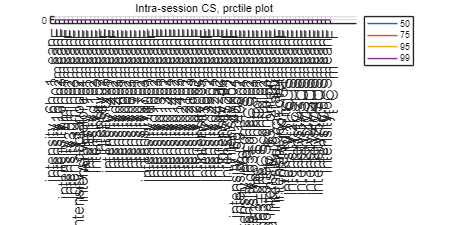

StructSimi_interSession = cell(length(StructData),3);  % original, modi, stat
for ci = 1:numSession
    data_1 = StructData(ci).Spike;
    data_1 = reshape(data_1,[],numVector,numCell);
    data_1 = squeeze(max(data_1,[],1));
    
    % CS and statistics
    TR_cs = cosineSimilarity(data_1);
    TR_cs_flag = tril(ones(numVector))-eye(numVector);
    TR_cs_flag(TR_cs_flag==0) = nan;
    TR_cs_1 = TR_cs.*TR_cs_flag;
    TR_cs_1 = reshape(TR_cs_1,[],1);
    TR_cs_1(isnan(TR_cs_1)) = [];
    prcValue = [50 75 95 99];
    TR_cs_stat = prctile(TR_cs_1,prcValue);
    
    % update info
    StructSimi_interSession{ci,1} = TR_cs;
    StructSimi_interSession{ci,2} = TR_cs_1;
    StructSimi_interSession{ci,3} = TR_cs_stat;
end

CS_interSession = cell2mat(StructSimi_interSession(:,3));
figure; hold on
plot(CS_interSession)
grid on
legend(string(prcValue'),"Location","bestoutside")
set(gcf,'Position',[50 50 600 300])
set(gca,'Xtick',1:numSession)
set(gca,'XtickLabel',StructPara.TimePoint)
title('Intra-session CS, prctile plot')

similarity cross-session

StructSimi_crossSession = cell(numSession);
CScrossSessionStat = [];
CScrossSessionStat.mean = zeros(numSession);
CScrossSessionStat.max = zeros(numSession);
prcValue = [50 75 95 99];
CScrossSessionStat.prcValue = zeros(numSession,numSession,length(prcValue));

for ci = 1:numSession
    data_1 = StructData(ci).Spike;
    data_1 = reshape(data_1,timeWindow,numVector,numCell);
    data_1 = squeeze(max(data_1,[],1));
    for cj = ci:numSession
        % pair-wise similarity across session
        data_2 = StructData(cj).Spike;
        data_2 = reshape(data_2,timeWindow,numVector,numCell);
        data_2 = squeeze(max(data_2,[],1));
        
        % cosine similarity cal
        CSMat = cosineSimilarity(data_1,data_2);
        if ci == cj
            CSMat(eye(numVector)==1) = nan;
        end
        StructSimi_crossSession{ci,cj} = CSMat;
        
        % stat 
        CSMat_1 = reshape(CSMat,[],1);
        CSMat_1(isnan(CSMat_1)) = [];
        CScrossSessionStat.mean(ci,cj) = mean(CSMat_1);
        CScrossSessionStat.max(ci,cj) = max(CSMat_1);
        CScrossSessionStat.prcValue(ci,cj,:) = prctile(CSMat_1,prcValue);
        
        CScrossSessionStat.mean(cj,ci) = CScrossSessionStat.mean(ci,cj);
        CScrossSessionStat.max(cj,ci) = CScrossSessionStat.max(ci,cj);
        CScrossSessionStat.prcValue(cj,ci,:) = CScrossSessionStat.prcValue(ci,cj,:);
    end
end

Visualization

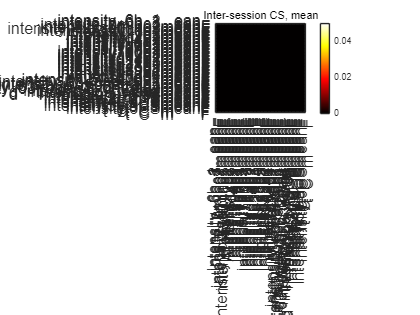

figure; 
imagesc(CScrossSessionStat.mean)
set(gca,'Xtick',1:numSession)
set(gca,'XtickLabel',StructPara.TimePoint)
set(gca,'Ytick',1:numSession)
set(gca,'YtickLabel',StructPara.TimePoint)
title('Inter-session CS, mean')
colormap('hot')
caxis([0 0.05]) 
colorbar
axis equal
set(gca,'XLim',[0 numSession]+0.5)
set(gca,'YLim',[0 numSession]+0.5)

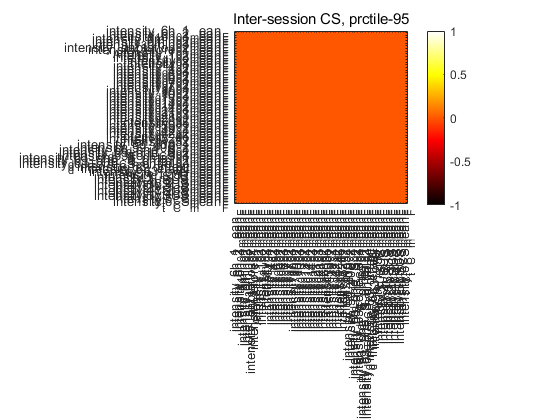

figure; 
imagesc(CScrossSessionStat.prcValue(:,:,3))
set(gca,'Xtick',1:numSession)
set(gca,'XtickLabel',StructPara.TimePoint)
set(gca,'Ytick',1:numSession)
set(gca,'YtickLabel',StructPara.TimePoint)
title('Inter-session CS, prctile-95')
colormap('hot')
colorbar
axis equal
set(gca,'XLim',[0 numSession]+0.5)
set(gca,'YLim',[0 numSession]+0.5)

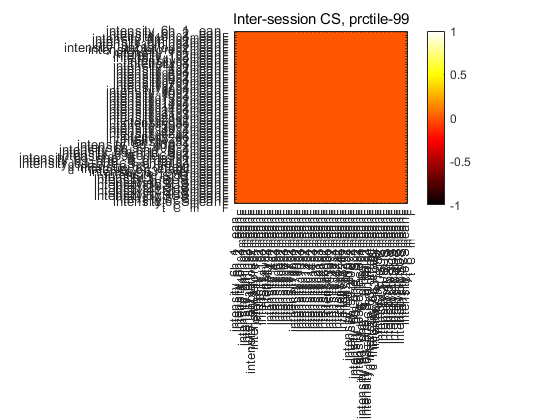


figure; 
imagesc(CScrossSessionStat.prcValue(:,:,4))
set(gca,'Xtick',1:numSession)
set(gca,'XtickLabel',StructPara.TimePoint)
set(gca,'Ytick',1:numSession)
set(gca,'YtickLabel',StructPara.TimePoint)
title('Inter-session CS, prctile-99')
colormap('hot')
colorbar
axis equal
set(gca,'XLim',[0 numSession]+0.5)
set(gca,'YLim',[0 numSession]+0.5)

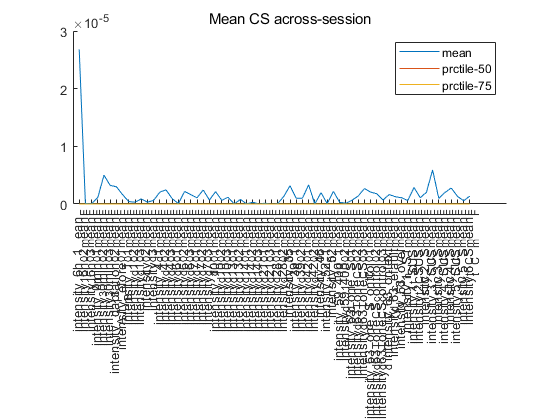


figure; hold on
plot(mean(CScrossSessionStat.mean))
plot(mean(CScrossSessionStat.prcValue(:,:,1)))
plot(mean(CScrossSessionStat.prcValue(:,:,2)))
set(gca,'Xtick',1:numSession)
set(gca,'XtickLabel',StructPara.TimePoint)
legend('mean','prctile-50','prctile-75')
title('Mean CS across-session')

## 马氏距离(Mahalanobis distance) 

Ensemble analysis based on statistics

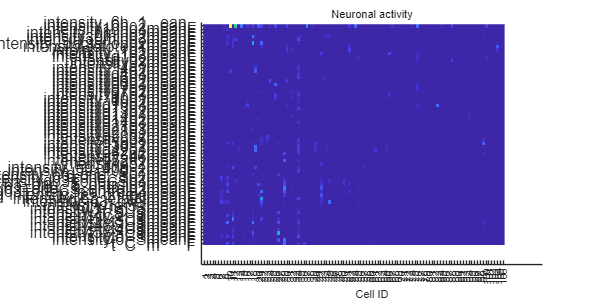

% % TRData=rand(100,2);  % 测试mahalanobis
% % D = pdist2(TRData,TRData(1,:),'mahalanobis');
% % D1=pdist(TRData,'mahalanobis');
% % D1=squareform(D1);
% % Err=D-D1(:,1);

% load('DataOrigi.mat')
SpikeStat=[]; % frequency | eman magnitude | CellNum * 2 * TimePoint
for ci=1:length(StructData)
    TRSpike=StructData(ci).Spike;
    TRIntensi=StructData(ci).Intensity;

    % intensity normalization
    SR1=prctile(TRIntensi,10);
    TRIntensi=TRIntensi-repmat(SR1,size(TRIntensi,1),1);

    TRIntensi_1=TRIntensi.*TRSpike;
    TRIntensi_1(TRIntensi_1==0)=nan;

    TRData=[sum(TRSpike,'omitnan'); ...
        mean(TRIntensi_1,'omitnan')]';
    TRData(isnan(TRData))=0;

    SpikeStat=cat(3,SpikeStat,TRData);
end
SpikeStat_1=SpikeStat;
SpikeStat_1=permute(SpikeStat_1,[1 3 2]);
[sa,sb,sc]=size(SpikeStat_1);  % CellNum * TimePoint * 2
SpikeStat_1=reshape(SpikeStat_1,[],2);

DistMahala = pdist2(SpikeStat_1,[0 0],'mahalanobis');
DistMahala=reshape(DistMahala,sa,sb);  % CellNum * TimePoint

figure
hold on
title('Neuronal activity')
imagesc(DistMahala')

set(gca,'YDir','reverse')
set(gca,'Ytick',1:sb)
set(gca,'YtickLabel',StructPara.TimePoint)
set(gca,'Xtick',1:sa)
set(gca,'XtickLabel',1:sa)

xlabel('Cell ID')
set(gcf,'position',[70 200 800 400])

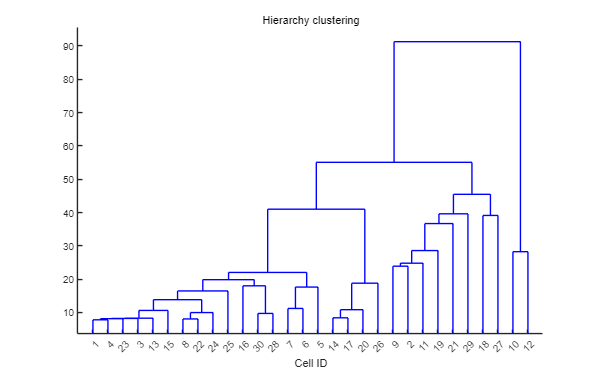


% % clustering
% % Construct agglomerative clusters from linkages
Z = linkage(DistMahala,'ward');
dendrogram(Z)
xlabel('Cell ID')
title('Hierarchy clustering')

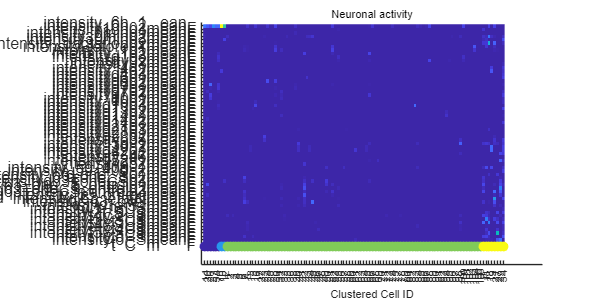


ClusterLabel = cluster(Z,'cutoff',2,'Depth',4);
[ca,cb]=sort(ClusterLabel,'ascend');
DistMahalaCluster=DistMahala';
DistMahalaCluster=DistMahalaCluster(:,cb);

figure
hold on
title('Neuronal activity')
imagesc(DistMahalaCluster)
ca_1=(ca-1)/(max(ca)-1)*max(DistMahalaCluster,[],'all');
scatter(1:sa,ones(1,sa)*sb+1,96,ca_1,'filled')

set(gca,'YDir','reverse')
set(gca,'Ytick',1:sb)
set(gca,'YtickLabel',StructPara.TimePoint)
set(gca,'Xtick',1:sa)
set(gca,'XtickLabel',cb)

xlabel('Clustered Cell ID')
set(gcf,'position',[70 200 800 400])

## Supporting functions

function  GraphPlotCircle(Graph,NodeName)
%UNTITLED2 Summary of this function goes here
%   Detailed explanation goes here
R=10;
N=size(Graph,1);
LocsX=R*cosd(linspace(0,360,N+1));
LocsY=R*sind(linspace(0,360,N+1));
LocsX(end)=[];
LocsY(end)=[];

Graph=Graph.*tril(ones(N));
[di,dj,dk]=find(Graph);
for ci=1:length(di)
    plot(LocsX([di(ci) dj(ci)]),LocsY([di(ci) dj(ci)]),...
        'LineWidth',1+dk(ci)/2,'color',[1 1 1]*0.5)
end

scatter(LocsX,LocsY,36,'filled','b')
text(LocsX,LocsY,NodeName)

end


function [cs,index] = sort_nat(c,mode)
%sort_nat: Natural order sort of cell array of strings.
% usage:  [S,INDEX] = sort_nat(C)
%
% where,
%    C is a cell array (vector) of strings to be sorted.
%    S is C, sorted in natural order.
%    INDEX is the sort order such that S = C(INDEX);
%
% Natural order sorting sorts strings containing digits in a way such that
% the numerical value of the digits is taken into account.  It is
% especially useful for sorting file names containing index numbers with
% different numbers of digits.  Often, people will use leading zeros to get
% the right sort order, but with this function you don't have to do that.
% For example, if C = {'file1.txt','file2.txt','file10.txt'}, a normal sort
% will give you
%
%       {'file1.txt'  'file10.txt'  'file2.txt'}
%
% whereas, sort_nat will give you
%
%       {'file1.txt'  'file2.txt'  'file10.txt'}
%
% See also: sort

% Version: 1.4, 22 January 2011
% Author:  Douglas M. Schwarz
% Email:   dmschwarz=ieee*org, dmschwarz=urgrad*rochester*edu
% Real_email = regexprep(Email,{'=','*'},{'@','.'})


% Set default value for mode if necessary.
if nargin < 2
    mode = 'ascend';
end

% Make sure mode is either 'ascend' or 'descend'.
modes = strcmpi(mode,{'ascend','descend'});
is_descend = modes(2);
if ~any(modes)
    error('sort_nat:sortDirection',...
        'sorting direction must be ''ascend'' or ''descend''.')
end

% Replace runs of digits with '0'.
c2 = regexprep(c,'\d+','0');

% Compute char version of c2 and locations of zeros.
s1 = char(c2);
z = s1 == '0';

% Extract the runs of digits and their start and end indices.
[digruns,first,last] = regexp(c,'\d+','match','start','end');

% Create matrix of numerical values of runs of digits and a matrix of the
% number of digits in each run.
num_str = length(c);
max_len = size(s1,2);
num_val = NaN(num_str,max_len);
num_dig = NaN(num_str,max_len);
for i = 1:num_str
    num_val(i,z(i,:)) = sscanf(sprintf('%s ',digruns{i}{:}),'%f');
    num_dig(i,z(i,:)) = last{i} - first{i} + 1;
end

% Find columns that have at least one non-NaN.  Make sure activecols is a
% 1-by-n vector even if n = 0.
activecols = reshape(find(~all(isnan(num_val))),1,[]);
n = length(activecols);

% Compute which columns in the composite matrix get the numbers.
numcols = activecols + (1:2:2*n);

% Compute which columns in the composite matrix get the number of digits.
ndigcols = numcols + 1;

% Compute which columns in the composite matrix get chars.
charcols = true(1,max_len + 2*n);
charcols(numcols) = false;
charcols(ndigcols) = false;

% Create and fill composite matrix, comp.
comp = zeros(num_str,max_len + 2*n);
comp(:,charcols) = double(s1);
comp(:,numcols) = num_val(:,activecols);
comp(:,ndigcols) = num_dig(:,activecols);

% Sort rows of composite matrix and use index to sort c in ascending or
% descending order, depending on mode.
[unused,index] = sortrows(comp);
if is_descend
    index = index(end:-1:1);
end
index = reshape(index,size(c));
cs = c(index);
end